# Lab 4: Graph in MATLAB (MA438)

[From Week 7, Feb 2023]

## Graphs in MATLAB

The simplest way to define a graph in MATLAB is by using the graph() function, with two integer arrays, $a$ and $b$ , as arguments: the resulting graph will have edges between $a(i)$ and $b(i)$, for i=1:length(a). 

Let's start with $P_n$, the path graph on $n$ vertices

n = 5;
a = [1 1 2 3 3 4];
b = [2 3 4 4 5 5];
House = graph(a, b)

House =   graph with properties:

    Edges: [6×1 table]
    Nodes: [5×0 table]


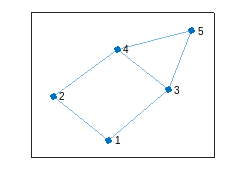

plot(House)

Here is another way: start with an empty graph, and add some edges.

G1 = graph()

G1 =   graph with properties:

    Edges: [0×1 table]
    Nodes: [0×0 table]


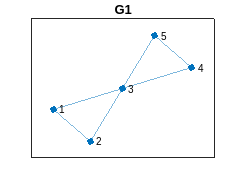

G1 = G1.addedge(1,2);
G1 = G1.addedge(3,2);
G1 = G1.addedge(1,3);
G1 = G1.addedge(3,4);
G1 = G1.addedge(4,5);
G1 = G1.addedge(3,5);
plot(G1); title("G1")

For example, here is a cycle graph, $C_4$

a = [1,2,3,4];
b = [2,3,4,1];
C4 = graph(a,b)

C4 =   graph with properties:

    Edges: [4×1 table]
    Nodes: [4×0 table]


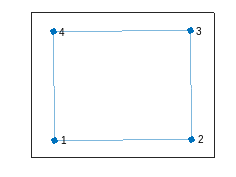

plot(C4)

One last example

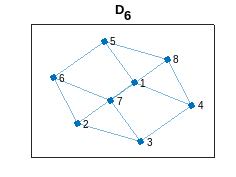

a = [1,2,3,4, 1,2,3,4, 5,6,7,5];
b = [2,3,4,1, 5,6,7,8, 6,7,8,8];
D6 = graph(a,b);
plot(D6); title('D_6')

## Adjacency Matrix

Alternatively, we can define the graph using its adjacency matrix. If a graph has $n$ vertices, then its adjacency matrix is the $n \times n$ matrix, $A$, with $a_{\textrm{ij}} =\left\lbrace \begin{array}{ll}
1 & \textrm{if}\;\textrm{there}\;\textrm{is}\;\textrm{an}\;\textrm{edge}\;\textrm{between}\;\textrm{vertices}\;i\;\textrm{and}\;j\;\\
0 & \textrm{otherwise}
\end{array}\right.$

When $G$ is not directed, $A$ is symmetric.

For example, $K_4$, the complete graph on 4 vertices has the adjacency matrix:

A4 = ones(4) - diag(ones(1,4))

A4 =      0     1     1     1
     1     0     1     1
     1     1     0     1
     1     1     1     0


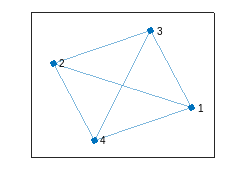

K4 = graph(A4);
plot(K4)

The adjacency matrix for the "house" graph (above) is:

full(House.adjacency())

ans =      0     1     1     0     0
     1     0     0     1     0
     1     0     0     1     1
     0     1     1     0     1
     0     0     1     1     0


### The graph of a matrix

You can pass $A$ to the graph function to create the associated graph.

K4 = graph(A4);
plot(K4)

Another example:

A = zeros(8);
A(1,2)=1; A(1,4)=1; A(1,6)=1;
A(1,3)=1; A(2,3)=1; A(4,5) = 1; A(5,6)=1;
A(5,7)=1; A(5,8)=1; 
A=A+A'  % make A symmetric, since this is non-directed

A =      0     1     1     1     0     1     0     0
     1     0     1     0     0     0     0     0
     1     1     0     0     0     0     0     0
     1     0     0     0     1     0     0     0
     0     0     0     1     0     1     1     1
     1     0     0     0     1     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     1     0     0     0


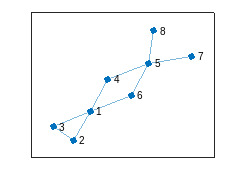

G8 = graph(A);
plot(G8)

If we have a graph, we can also extract the Adjacency Matrix. By default, this is "sparse". so we will convert to full.

A4 = full(C4.adjacency)

A4 =      0     1     0     1
     1     0     1     0
     0     1     0     1
     1     0     1     0


What happens if $A$ has diagonal entries?

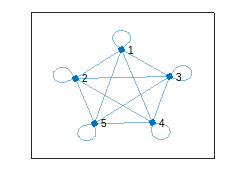

F = ones(5);
F(1,2)=2; F(2,1)=2;
GF = graph(F);
plot(GF)

### Computing with the Adjacency matrix

The adjacency matrix has many applications. A simple one is the the row (or column) suns of $A$ give you the degree of each vertex:

plot(G8)

d=sum(A)

d =      4     2     2     2     4     2     1     1


for i=1:length(d)
   fprintf("Vertex %d has degree %d\n", i, d(i))
end

Vertex 1 has degree 4
Vertex 2 has degree 2
Vertex 3 has degree 2
Vertex 4 has degree 2
Vertex 5 has degree 4
Vertex 6 has degree 2
Vertex 7 has degree 1
Vertex 8 has degree 1


Similarly, we can count the number of edges in the graph: it is half the sum of all the entries in the graph.

Here is another useful property. Set $e^{(i)}$ to be the vector where $e^{(i)}_i=1$, and all other entries are zero; that is, $e^{(i)}$ is the $i$th row of the identity matrix. Now compute $v=Ae^{(i)}$. Then $v_j=1$ if and only if $i$ is a neightbour of $j$ in $G$.

A consequence of this is that, if $B=A^k$, then $b_{ij}$ is the number of paths of length $k$ between vertex $i$ and vertex $j$:

plot(G8)

B=A^3

B =      2     5     5     6     0     6     2     2
     5     2     3     1     2     1     0     0
     5     3     2     1     2     1     0     0
     6     1     1     0     6     0     0     0
     0     2     2     6     0     6     4     4
     6     1     1     0     6     0     0     0
     2     0     0     0     4     0     0     0
     2     0     0     0     4     0     0     0


## Graphs as Objects

Graphs are examples of *objects* in MATLAB. The full ramifications of that is beyond this module. But, roughly, it means, that, unlike, say, a matrix, it as properties that we can check and change. Try these:

Number_of_edges = C4.numedges

Number_of_edges = 4

C4.numnodes

ans = 4

C4.Edges

ans = 4×1 table
    EndNodes
    ________

     1    2 
     1    4 
     2    3 
     3    4 


And these:

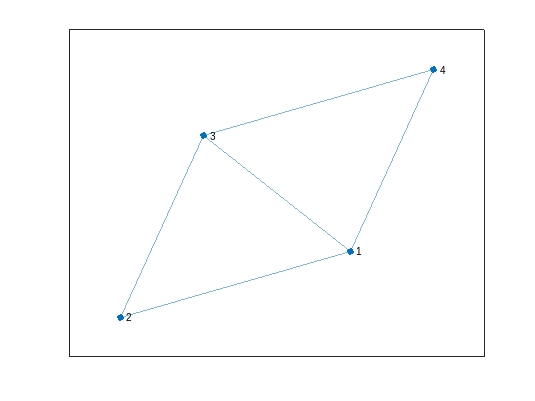

G=C4.addedge(1,3);
plot(G)

There are various built-in functions for graphs (though fewer than you might think). For example, the `minspantree()` function returns a minimum spanning tree for the graph. Here is an example of using it along with `highlight()`.

M34 = K34.minspantree()

M34 =   graph with properties:

    Edges: [6×1 table]
    Nodes: [7×0 table]


h = plot(K34, 'EdgeColor','green', 'LineWidth',2, 'MarkerSize',10)

h =   GraphPlot with properties:

     NodeColor: [0 0.4470 0.7410]
    MarkerSize: 10
        Marker: 'o'
     EdgeColor: [0 1 0]
     LineWidth: 2
     LineStyle: '-'
     NodeLabel: {'1'  '2'  '3'  '4'  '5'  '6'  '7'}
     EdgeLabel: {}
         XData: [0.0782 0.0448 -0.1121 -1.7761 1.6592 -1.6689 1.7749]
         YData: [0.0050 -1.2084 1.2042 0.7596 1.0166 -0.9797 -0.7973]
         ZData: [0 0 0 0 0 0 0]

  Show all properties


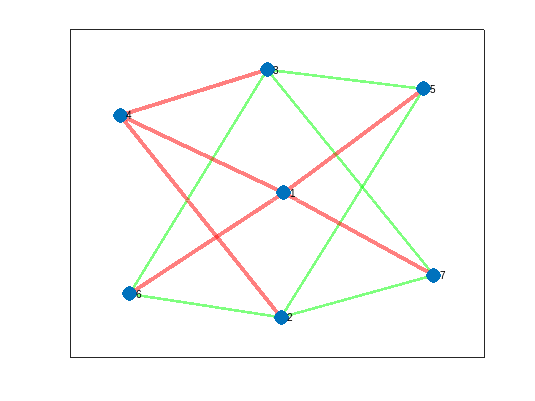

h.highlight(M34, 'EdgeColor','red', 'LineWidth',3)

## Bipartite Graphs

From Rachel's lectures, you know what a bipartite graph is. Let's construct $K_{3,4}$. We'll let the parts be $\{1,2,3\}$ and $\{4,5,6,7\}$. We'll make it with a for-loop (though there are oth   er ways).

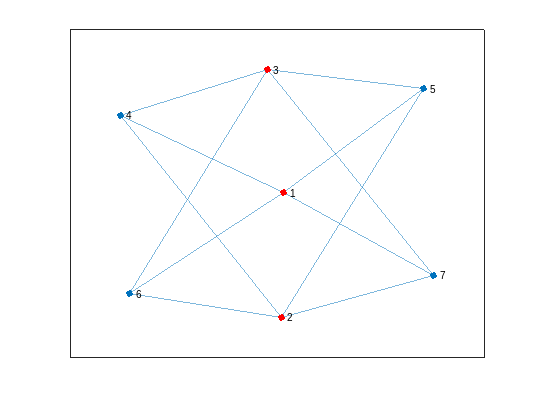

K34 = graph(); % empty graph
for i=1:3
   for j=4:7
      K34=K34.addedge(i,j);
   end
end
h=plot(K34);
highlight(h, [1:3], 'NodeColor','red')

Here the `highlight()` function is used to distinguish some vertices. We can also do this for edges, which will prove very useful.

The adjacency matrix of a bipartite graph can be revealing, at least of the vertices are ordered in a certain way,

full(K34.adjacency())

ans =      0     0     0     1     1     1     1
     0     0     0     1     1     1     1
     0     0     0     1     1     1     1
     1     1     1     0     0     0     0
     1     1     1     0     0     0     0
     1     1     1     0     0     0     0
     1     1     1     0     0     0     0


Determining if a graph is bipartite is not too hard: one can use a breadth-first search. We'll look at that another time.

## Directed Graphs

To make a directed grap, use the `digraph()` function. Example: let's make a random graph with 6 vertices, and 12 edges

D = digraph();
D = addnode(D, 6)

D =   digraph with properties:

    Edges: [0×1 table]
    Nodes: [6×0 table]


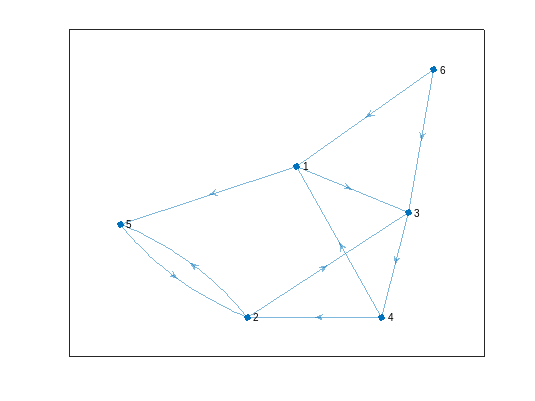

while(D.numedges < 10)
   a = randi(6,1,1);
   b = randi(6,1,1);
   if ((a ~= b) && (findedge(D,a,b)==0))
      D = D.addedge(a,b);
   end
end
plot(D)